% select exp
E_struct = expCell{3};

% overall corr
DM1 = zscore(E_struct{1}.DataMatrix);
DM2 = zscore(E_struct{2}.DataMatrix);

ml = min(size(DM1,1), size(DM2,1));
DM1 = DM1(1:ml,:);
DM2 = DM2(1:ml,:);

disp(corr2(mean(DM1,2), mean(DM2,2)))

    0.2140



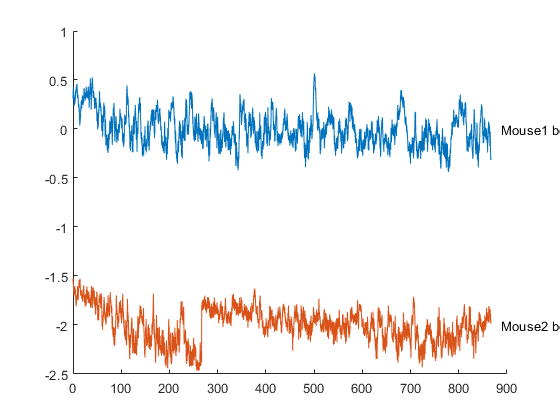

ans = 0.2140

Corr_Behav(E_struct{1},E_struct{2}, {'all,none','all,none'})

% all behaviors
E_struct{1}.Behavior.EventNames

ans = 6×1 cell array
    {'approach'    }
    {'dig'         }
    {'escape'      }
    {'selfgrooming'}
    {'sniffing'    }
    {'stand'       }


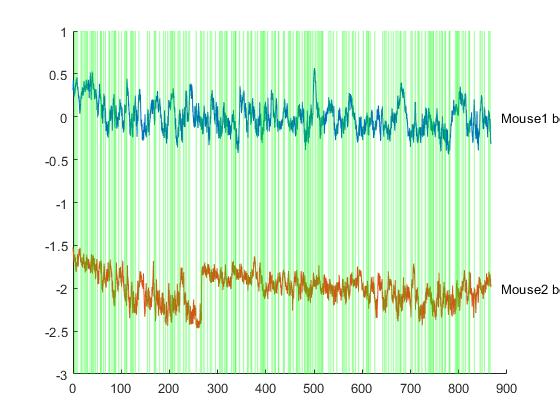

within any behavior: 0.272867

% in/out behav corr
fprintf('within any behavior: %f', Corr_Behav(E_struct{1}, E_struct{2}, {'all', 'all'}));

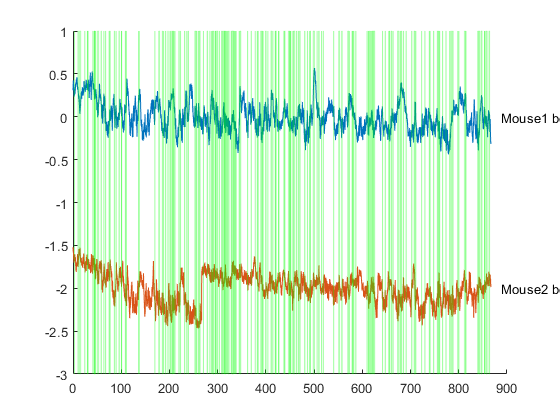

1 doing sth 2 not doing anything: 0.125420

% one doing one not doing
fprintf('1 doing sth 2 not doing anything: %f', Corr_Behav(E_struct{1}, E_struct{2}, {'all', 'none'}));

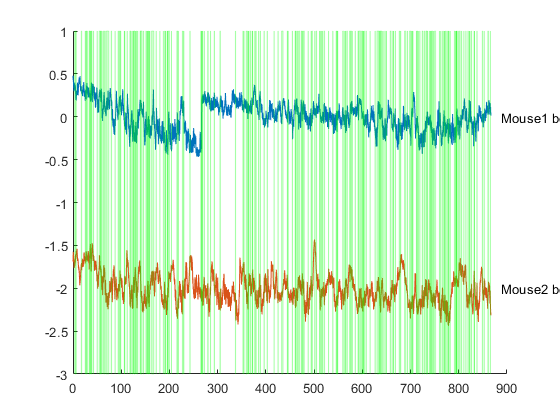

2 doing sth 1 not doing anything: 0.368525

fprintf('2 doing sth 1 not doing anything: %f', Corr_Behav(E_struct{2}, E_struct{1}, {'all', 'none'}));

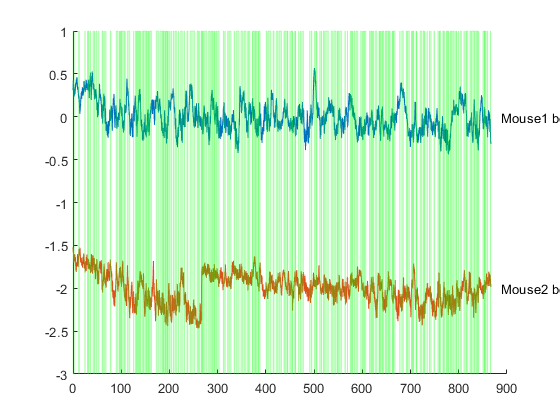

both not doing anything: 0.126923

% both not doing anything
fprintf('both not doing anything: %f', Corr_Behav(E_struct{1}, E_struct{2}, {'none', 'none'}));

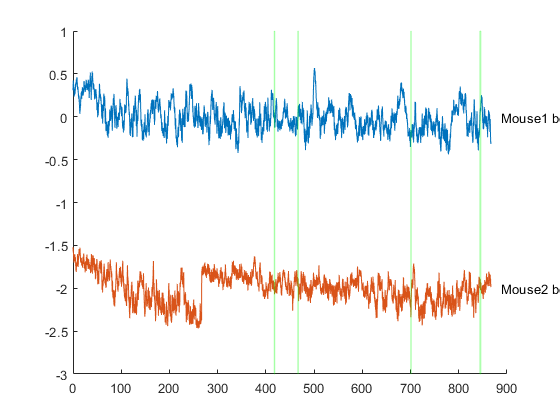

both stand: 0.825764

% during stand
fprintf('both stand: %f', Corr_Behav(E_struct{1}, E_struct{2},{'stand','stand'}));

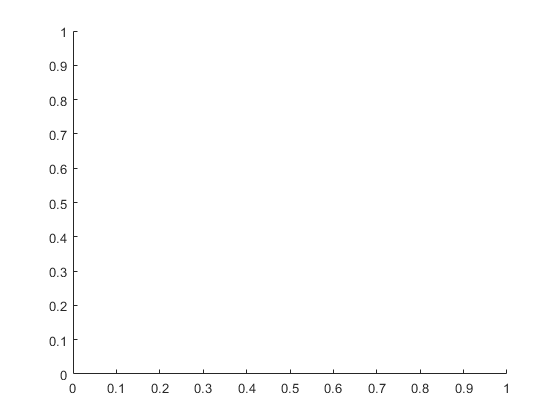

Array indices must be positive integers or logical values.

Error in Corr_Behav (line 115)
text(tm(end)/fr+20, 0, 'Mouse1 behavior');

% during sniffing
fprintf('both sniffing: %f', Corr_Behav(E_struct{1}, E_struct{2},{'sniffing','approach,attack,defend,escape,mount,running,selfgrooming,socialgrooming,stand,none'}));

% during try passing
% fprintf('both try passing: %f', Corr_Behav(E_struct{1}, E_struct{2},{'trypassing','trypassing'}));